clear all;
addpath('gpstoolbox_path'); % 替換為 gpstoolbox 的安裝路徑


% 讀取 RINEX 檔案
obs = rinexread('D:\gps file\12f roof  香菇\rtklib\LOG01077.obs'); % 觀測數據
nav = rinexread('D:\gps file\12f roof  香菇\rtklib\LOG01077.nav'); % 導航數據

prn = obs.Galileo.SatelliteID;
snr = obs.Galileo.S1X;
el  = obs.Elevation;

Unrecognized field name "Elevation".

az  = obs.Azimuth;

figure;
skyplot(az, el, prn, 'SNR', snr);
colorbar;
title('Skyplot with SNR');

% 提取衛星數據
satInfo = obs.Galileo.SatelliteID;
time = obs.Galileo.Time;

% 計算每個衛星在每個時間點的仰角和方位角
elevation = [];
azimuth = [];
for i = 1:length(time)
    for j = 1:length(satInfo)
        % 使用 ephemeris 計算衛星位置，避免變數名稱衝突
        satPosition = satPos(nav, time(i), satInfo(j));
        % 計算方位角與仰角
        [az, el] = ecef2azel(satPosition, obs.ApproxPos);
        azimuth(i, j) = az;
        elevation(i, j) = el;
    end
end

% Skyplot 繪製
figure;
hold on;
for j = 1:length(satInfo)
    polarplot(deg2rad(azimuth(:, j)), 90 - elevation(:, j), 'DisplayName', num2str(satInfo(j))); % 使用 num2str 顯示衛星 ID
end
title('衛星軌跡 Skyplot');
legend('show');
hold off;




% 檢查 rinexread 回傳的結構
disp(obs);

% 提取衛星資訊
% sat_info = obs.ObservationData;  % RINEX 觀測數據
sat_info = obs.GPS;  % RINEX 觀測數據

% 解析衛星 ID (PRN)
prn = unique(sat_info.SatelliteID);

% 取得信號強度 (SNR) - RINEX 內可能標示為 C/N0
snr_idx = find(strcmp(obs.ObservationTypes, 'C/N0')); % 確認 SNR 欄位索引
if isempty(snr_idx)
    error('RINEX 檔案未提供 C/N0 (信號強度) 資料');
end

% 初始化變數
az = [];
el = [];
snr = [];

% 迴圈處理所有衛星
for i = 1:length(prn)
    idx = (sat_info.SatelliteID == prn(i));
    
    % 提取方位角 (Azimuth)、仰角 (Elevation)
    az = [az; sat_info.Azimuth(idx)];
    el = [el; sat_info.Elevation(idx)];
    
    % 提取對應的 SNR 值
    snr = [snr; sat_info.Observation(idx, snr_idx)];
end

% 繪製 Skyplot
figure;
skyplot(az, el, prn, 'SNR', snr);
colorbar;
title('Skyplot with SNR');

clear;clc;
close all
 
filename='wtf.txt';
fid = fopen(filename, 'r');MAXSAT=211;ix=0;
az=zeros(1,MAXSAT);el=zeros(1,MAXSAT);
% read file
while(1)
    line=fgetl(fid);
    if (line == -1)
        break;
    end
    if(line(1:1)=='>')
        fprintf('%s\n',line);ix=ix+1;
        yr=str2double(line(3:6));mon=str2double(line(8:9));day=str2double(line(11:12));
        hr=str2double(line(14:15));min=str2double(line(17:18));sec=str2double(line(20:26));
    else
        if(line(1:1)=='G')
            prn_s=0;
        elseif(line(1:1)=='R')
            prn_s=32;
        elseif(line(1:1)=='E')
            prn_s=59;
        elseif(line(1:1)=='C')
            prn_s=95;
        end
        sat=prn_s+str2double(line(2:3));
        az(ix,sat)=str2double(line(4:12));el(ix,sat)=str2double(line(13:21));
    end
end

> 2022/06/14 12:00:00.000   45
> 2022/06/14 12:00:01.000   45
> 2022/06/14 12:00:02.000   45
> 2022/06/14 12:00:03.000   45
> 2022/06/14 12:00:04.000   45
> 2022/06/14 12:00:05.000   45
> 2022/06/14 12:00:06.000   45
> 2022/06/14 12:00:07.000   45
> 2022/06/14 12:00:08.000   45
> 2022/06/14 12:00:09.000   45
> 2022/06/14 12:00:10.000   45
> 2022/06/14 12:00:11.000   45
> 2022/06/14 12:00:12.000   45
> 2022/06/14 12:00:13.000   45
> 2022/06/14 12:00:14.000   45
> 2022/06/14 12:00:15.000   45
> 2022/06/14 12:00:16.000   45
> 2022/06/14 12:00:17.000   45
> 2022/06/14 12:00:18.000   45
> 2022/06/14 12:00:19.000   45
> 2022/06/14 12:00:20.000   45
> 2022/06/14 12:00:21.000   45
> 2022/06/14 12:00:22.000   45
> 2022/06/14 12:00:23.000   45
> 2022/06/14 12:00:24.000   45
> 2022/06/14 12:00:25.000   45
> 2022/06/14 12:00:26.000   45
> 2022/06/14 12:00:27.000   45
> 2022/06/14 12:00:28.000   45
> 2022/06/14 12:00:29.000   45
> 2022/06/14 12:00:30.000   45
> 2022/06/14 12:00:31.000   45
> 2022/0

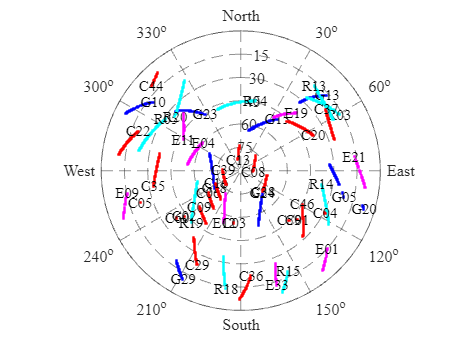

 
tip=1;ms=5;
for i=1:MAXSAT
    id=find(abs(az(:,i))>0);
    if ~isempty(id)
        [row,col]=size(id);
        rho = rad2deg(el(id,i));% 极径=90度-高度角(deg)
        theta =az(id,i); % 极角=方位角(rad)
        if(i<33)
            polarplot(theta, rho, 'b.','MarkerSize',ms);
            leg{tip}=num2str(i,'G%02d');tip=tip+1;%#ok
        elseif(i<32+27)
            polarplot(theta, rho, 'c.','MarkerSize',ms);
            leg{tip}=num2str(i-32,'R%02d');tip=tip+1;%#ok
        elseif(i<32+27+36)
            polarplot(theta, rho, 'm.','MarkerSize',ms);
            leg{tip}=num2str(i-32-27,'E%02d');tip=tip+1;%#ok
        else
            polarplot(theta, rho, 'r.','MarkerSize',ms);
            leg{tip}=num2str(i-95,'C%02d');tip=tip+1;%#ok
        end
        text(theta(end), rho(end), leg{tip-1}, 'HorizontalAlignment', 'center',...
            'VerticalAlignment', 'middle','FontName','Times New Roman');
        hold on
    end
end
rlim([0,90]); % 设置极径范围（0到90度）
thetaticks([0:30:360]);%#ok
ax=gca;
ax.ThetaZeroLocation = 'top';
ax.RTick=[0,15,30,45,60,75,90];
ax.RTickLabel={'','15','30','45','60','75',''};
ax.RDir='reverse';
ax.ThetaTickLabel={'North','30^{o}','60^{o}','East','120^{o}','150^{o}',...
    'South','210^{o}','240^{o}','West','300^{o}','330^{o}'};
set(gca,'FontName','Times New Roman','ThetaDir','clockwise',...
    'GridLineStyle','--','gridalpha',0.5,'Fontsize',11);